Terminology: 

    AR asset richneess = 1-AP

    AP asset poorness = EVBV

    AI asset intensity= 1/EVBV

    EV = enterprise value = Market Capitalization - BV of Equity - Total Liability

    LM = leverage multiplier = Debt/EBITDA

    BL = book leverage = Debt/Book value

    Vol = Volatility of Income

    EL = Enterprise Leverage = Debt/EV = target (represent capital structure)


%import data
[D, modelD] =in.getMultiYearData();
modelD.AI=1./modelD.EVBV;
modelD.Vol_lo=1-modelD.Vol_hi;

%set up cross validation
[Dtrain, Dtest] = cv.splitTableByHoldout(modelD, 0.3);


Model 1 based on H1a, H1b, H2a, H2b

%train
model1 = fitlm(Dtrain, 'EL~ LM:AP+BL:AR -1')

model1 = Linear regression model:
    EL ~ BL:AR + LM:AP

Estimated Coefficients:
             Estimate       SE        tStat       pValue  
             ________    _________    ______    __________

    BL:AR     0.91497     0.030445    30.053    3.2332e-71
    LM:AP    0.038575    0.0053873    7.1604    2.1039e-11


Number of observations: 178, Error degrees of freedom: 176
Root Mean Squared Error: 0.12

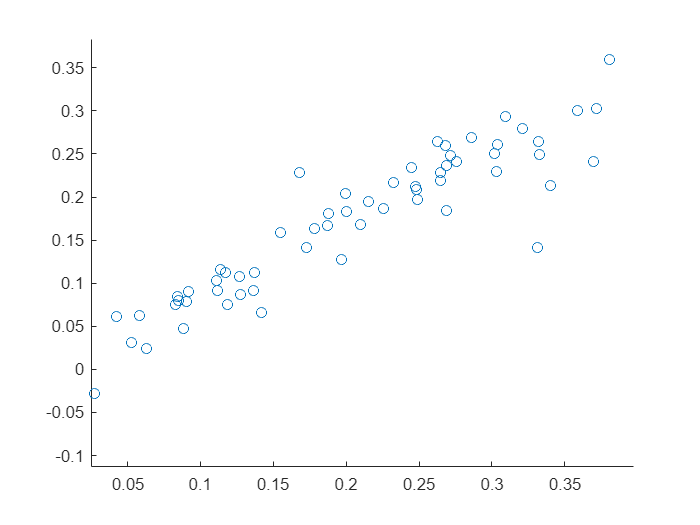

%test
Yactual = Dtest.EL;
Yest = predict(model1,Dtest);
figure; 
ylabel('Yest');
xlabel('Yactual');
scatter(Yactual, Yest) 

Model 2 based on H1a, H1b, H2a, H2b and Vol

%train
model2 = fitlm(Dtrain, 'EL~ LM:AP+BL:AR+Vol-1')

model2 = Linear regression model:
    EL ~ Vol + BL:AR + LM:AP

Estimated Coefficients:
             Estimate       SE        tStat       pValue  
             ________    _________    ______    __________

    Vol        1.0094      0.17731    5.6929    5.1759e-08
    BL:AR     0.79836     0.034729    22.988    9.4124e-55
    LM:AP    0.032073    0.0050924    6.2983    2.3567e-09


Number of observations: 178, Error degrees of freedom: 175
Root Mean Squared Error: 0.11

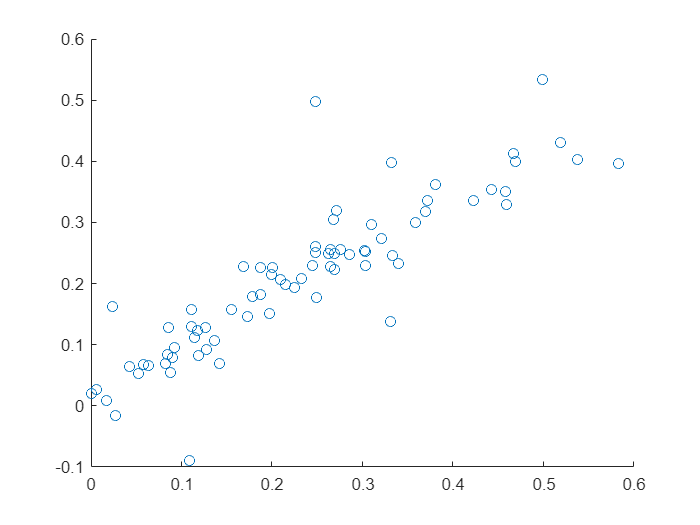

%test
Yactual = Dtest.EL;
Yest = predict(model2,Dtest);
figure; 
ylabel('Yest');
xlabel('Yactual');
scatter(Yactual, Yest) 

Model 3 based on H1a, H1b, H2a, H2b, H1c, H2c

model3 = fitlm(Dtrain, 'EL~ LM:AP+BL:AR+Vol_lo:LM+Vol_lo:BL-1')

model3 = Linear regression model:
    EL ~ LM:Vol_lo + BL:Vol_lo + BL:AR + LM:AP

Estimated Coefficients:
                  Estimate        SE         tStat        pValue  
                 __________    _________    ________    __________

    LM:Vol_lo    -0.0042468    0.0044625    -0.95166       0.34259
    BL:Vol_lo       0.27847     0.059282      4.6973    5.3295e-06
    BL:AR           0.77592     0.037585      20.644    1.1775e-48
    LM:AP          0.020028    0.0060592      3.3054     0.0011518


Number of observations: 178, Error degrees of freedom: 174
Root Mean Squared Error: 0.109

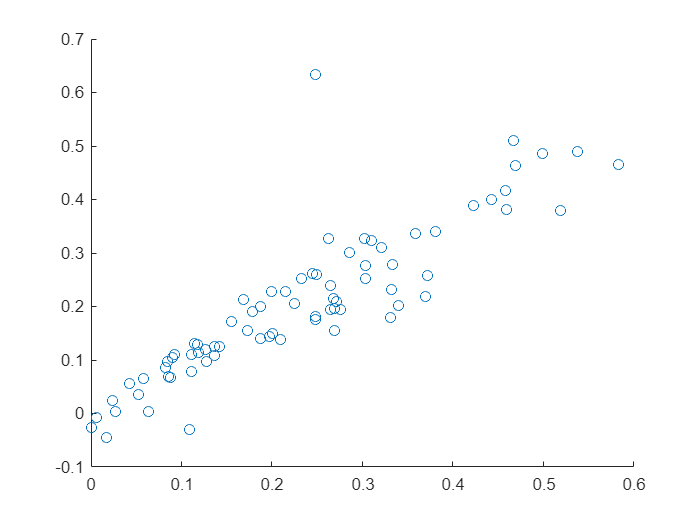

%test
Yactual = Dtest.EL;
Yest = predict(model3,Dtest);
figure; 
ylabel('Yest');
xlabel('Yactual');
scatter(Yactual, Yest) 

Model 4 based on H1a, H1b, H2a, H2b, H2c (Note: Vol_lo:LM is reduced due to high p-value)

model4 = fitlm(Dtrain, 'EL~ LM:AP+BL:AR+Vol_lo:BL-1')

model4 = Linear regression model:
    EL ~ BL:Vol_lo + BL:AR + LM:AP

Estimated Coefficients:
                 Estimate       SE        tStat       pValue  
                 ________    _________    ______    __________

    BL:Vol_lo     0.23566       0.0386    6.1051    6.4464e-09
    BL:AR         0.76822     0.036693    20.937    1.5618e-49
    LM:AP        0.022258    0.0055864    3.9843    9.9163e-05


Number of observations: 178, Error degrees of freedom: 175
Root Mean Squared Error: 0.109

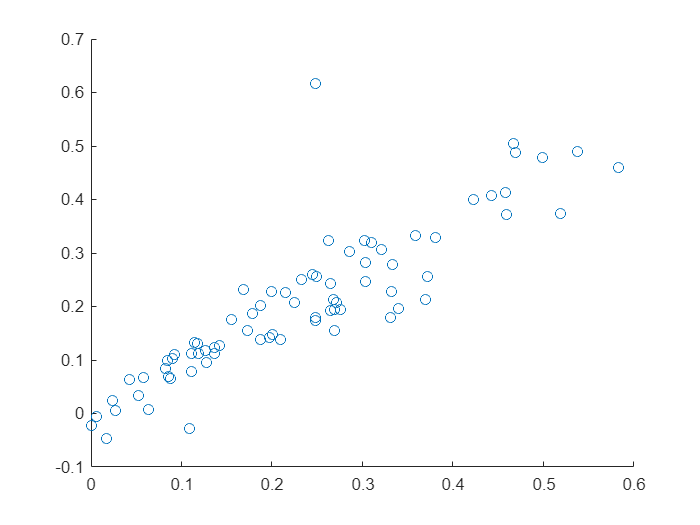

%test
Yactual = Dtest.EL;
Yest = predict(model4,Dtest);
figure; 
ylabel('Yest');
xlabel('Yactual');
scatter(Yactual, Yest)

Rsquared

%test
model1.Rsquared

ans = struct with fields:
    Ordinary: 0.3795
    Adjusted: 0.3760


model2.Rsquared

ans = struct with fields:
    Ordinary: 0.4765
    Adjusted: 0.4705


model3.Rsquared

ans = struct with fields:
    Ordinary: 0.4911
    Adjusted: 0.4823


model4.Rsquared

ans = struct with fields:
    Ordinary: 0.4885
    Adjusted: 0.4826
